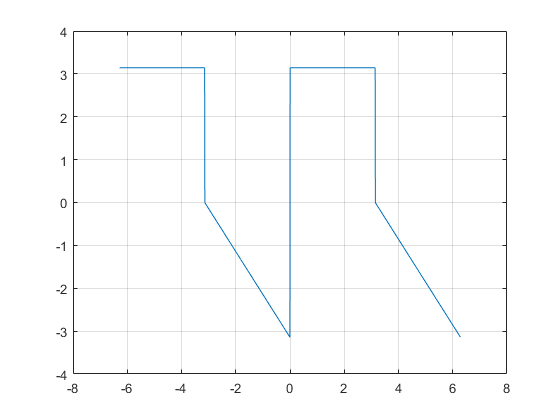

f = @(x) (x).*(0 <= x & x < pi) + (pi-x).*(pi <= x < 2*pi);
x = linspace(0, 2*pi, 1000);
y = f(x);

ry = repmat(y, 1, 2);
rx = linspace(-2*pi, 2*pi, length(ry));
plot(rx, ry);
grid on;

syms t;
f = 1.*(heaviside(t+2)-heaviside(t-2))+(-1).*(heaviside(t-2)-heaviside(t-4))

$$f = \mathrm{heaviside}\left(t+2\right)-2\,\mathrm{heaviside}\left(t-2\right)+\mathrm{heaviside}\left(t-4\right)$$

fourier(f)

$$ans = -2\,{\mathrm{e}}^{-2\,w\,\mathrm{i}}\,\left(\pi \,\delta (w)-\frac{\mathrm{i}}{w}\right)+{\mathrm{e}}^{2\,w\,\mathrm{i}}\,\left(\pi \,\delta (w)-\frac{\mathrm{i}}{w}\right)+{\mathrm{e}}^{-4\,w\,\mathrm{i}}\,\left(\pi \,\delta (w)-\frac{\mathrm{i}}{w}\right)$$

laplace(f)

$$ans = \frac{{\mathrm{e}}^{-4\,s}}{s}-\frac{2\,{\mathrm{e}}^{-2\,s}}{s}+\frac{1}{s}$$

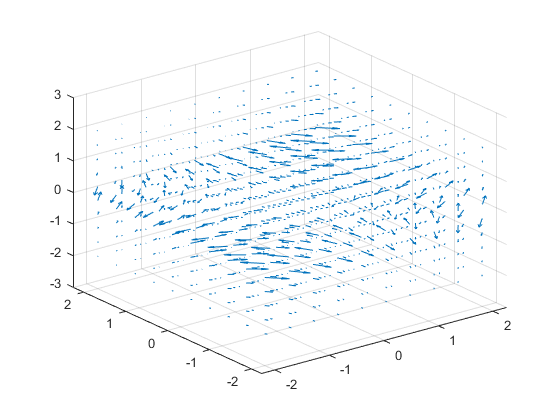

a = linspace(-2, 2, 10);
[x, y, z] = meshgrid(a, a, a);
u = x./z;
v = -y./z;
w = z/4;

quiver3(x, y, z, u, v, w);